## ELECTRA: CW-ESR SPECTRUM BROADENED BY INTRAMOLECULAR ELECTRON TRANSFER

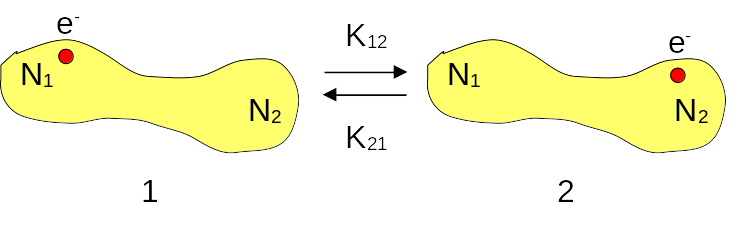

### Model parameters

$\omega_0$: electron Larmor frequency / GHz (w0 in the code)

$A_1,A_2$: hyperfine coupling constants with nitrogens 1 and 2 / Gauss (A1 and A2 in the code)

$K_{1,2}, K_{2,1}$: jump rate constants / MHz (K12 and K21 in the code)

$R_1,R_2
$: inverse of $T_2$ / MHz (R1 and R2 in the code)

$\rho_1$: Boltzmann weight of the first configuration (p1 in the code; also, p2 = 1.0 - p1)

w0  = 9.2244; fitw0  = true; % GHz
A1  = 8.677; fitA1  = true; minA1  = 6; maxA1  = 12; % Gauss
A2  = 8.677; fitA2  = true; minA2  = 6; maxA2  = 12; % Gauss
K12 = 15.447; fitK12 = true; minK12 = 0; maxK12 = 500; % MHz
K21 = 15.447; fitK21 = true; minK21 = 0; maxK21 = 500; % MHz
R1  = 9.078; fitR1  = true; minR1  = 1; maxR1  = 50; % MHz
R2  = 9.078; fitR2  = true; minR2  = 1; maxR2  = 50; % MHz
sH  = 2; fitSH  = true; % MHz

If the molecule is symmetric, checking the option poses these constraints in the fitting: $A_1=A_2$, $K_{1,2}=K_{2,1}$, and/or $R_1=R_2$.

SymmetricMol = true;

% Scale frequencies
w0 = w0 * 1e9; % Hz
freq_scale = w0;

w0 = 1.0;

gammae = 2.8025e6; % Hz / Gauss
wA1 = gammae * A1 / freq_scale;
wA2 = gammae * A2 / freq_scale;
minA1 = gammae * minA1 / freq_scale;
minA2 = gammae * minA2 / freq_scale;
maxA1 = gammae * maxA1 / freq_scale;
maxA2 = gammae * maxA2 / freq_scale;

K12 = K12 * 1e6 / freq_scale;
K21 = K21 * 1e6 / freq_scale;
minK12 = minK12 * 1e6 / freq_scale;
minK21 = minK21 * 1e6 / freq_scale;
maxK12 = maxK12 * 1e6 / freq_scale;
maxK21 = maxK21 * 1e6 / freq_scale;


R1  = R1 * 1e6 / freq_scale;
R2  = R2 * 1e6 / freq_scale;
minR1  = minR1 * 1e6 / freq_scale;
minR2  = minR2 * 1e6 / freq_scale;
maxR1  = maxR1 * 1e6 / freq_scale;
maxR2  = maxR2 * 1e6 / freq_scale;

% Hydrogens
wAH = gammae * aH / freq_scale;
sH = sH * 1e6 / freq_scale;

% Boltzmann factor
nConfigurations = 2;
r = K21/K12;
p2 = 1.0 / (1.0 +r);
p1 = 1.0 - p2;
p1 = sqrt(p1);
p2 = sqrt(p2);

File with experimental spectrum: two columns, space or tab separated: field/Gauss signal

expFile = "./FV1AT300_01.txt";

### Build spin basis


$$\vert \sigma\rangle\rangle=
\vert m_{S},m'_{S}\rangle\rangle\otimes
\vert m_{I_1},m'_{I_1}\rangle\rangle\otimes
\vert m_{I_2},m'_{I_2}\rangle\rangle$$



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Summary of fitting parameters:


w0  = 3291.388 Gauss


A1  = 8.677 Gauss


A2  = 8.677 Gauss


K12 = 498.8394 MHz


K21 = 498.8394 MHz


R1  = 1.0158 MHz


R2  = 1.0158 MHz


sH  = 4.4666 MHz


p1  = 0.5


p2  = 0.5


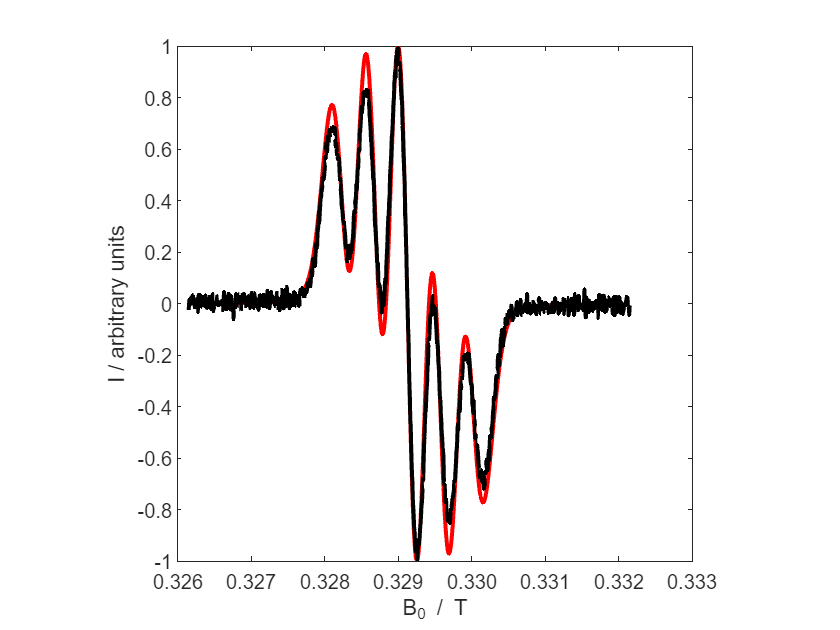

I1 = 1;
I1mult = 2 * I1 + 1;
nBasis = 4 * I1mult^2 * I1mult^2;
basis = zeros(nBasis, 6);

shift = 1;
for mS = -0.5:1:0.5
    for mSp = -0.5:1:0.5
        for mI1 = -I1:1:I1
            for mI1p = -I1:1:I1
                for mI2 = -I1:1:I1
                    for mI2p = -I1:1:I1
                        basis(shift,:)=[mS mSp mI1 mI1p mI2 mI2p];
                        shift = shift + 1;
                    end
                end
            end
        end
    end
end

% Load experimental file to perform fitting, or make theoretical
% calculation

expFound = 0;

if expFile ~= ""
    expSpectrum = load(expFile);
    expFound = 1;
    
    % Normalize per area
    dB = expSpectrum(2,1) - expSpectrum(1,1);
    iExpSpectrum = (dB * gammae / freq_scale) * sum(expSpectrum(:,2));
    expSpectrum(:,2) = expSpectrum(:,2) ./ abs(iExpSpectrum);
end

if expFound == 0
    sweep  =  80; % Gauss (used if no exp file has been loaded)
    hsweep = 0.5 * sweep * gammae / freq_scale;
    dw = linspace(w0 - hsweep, w0 + hsweep, 1000);

    data    = [w0 wA1 wA2 K12 K21 R1 R2 sH];
    theoSpectrum = calcSpectrum(data, dw, zeros(size(data)), data, basis);
 
    % Plot
    dw = dw .* freq_scale / (1e4 * gammae);
    l=plot(dw, theoSpectrum);
    set(l,"linewidth",2,'color','k','LineStyle',"-");
    axis square;
    xlabel('B_0 / T');
    xtickformat('%1.3f');
    ylabel ('I / arbitrary units');
else % Fitting
    sweep = expSpectrum(end,1) - expSpectrum(1,1);
    hsweep = 0.5 * sweep * gammae / freq_scale;
    dw = linspace(w0 - hsweep, w0 + hsweep, size(expSpectrum,1));
    
    % Prepare fitting boundaries and constraints
    data    = [w0    wA1   wA2   K12    K21    R1    R2    sH   ];
    pToFit  = [fitw0 fitA1 fitA2 fitK12 fitK21 fitR1 fitR2 fitSH];
    minData = [-inf  minA1 minA2 minK12 minK21 minR1 minR2 0    ];
    maxData = [+inf  maxA1 maxA2 maxK12 maxK21 maxR1 maxR2 maxR1];
    
    if SymmetricMol == 1
        if (fitA1 ~= fitA2) || (fitK12 ~= fitK21) || (fitR1 ~= fitR2)
            disp("Error: the selection of fitting parameters is incompatible with the constraint of symmetry");
            return
        end
        Me  = fitA1 + fitK12 + fitR1;
        if (Me > 0)
            Aeq = zeros(Me, sum(pToFit));
            beq = zeros(Me, 1);
            shift = fitw0;
            for m = 1:Me
                Aeq(m, 2 * (m - 1) + 1 + shift) =  1.0;
                Aeq(m, 2 * (m - 1) + 2 + shift) = -1.0;
            end
        end
    end

    % Build initial guess
    nfit = sum(pToFit);
    p0 = zeros(nfit, 1);
    lb = zeros(nfit, 1);
    ub = zeros(nfit, 1);
    count = 1;
    for i = 1:max(size(pToFit))
        if pToFit(i) == 1
            p0(count) = data(i);
            lb(count) = minData(i);
            ub(count) = maxData(i);
            count = count + 1;
        end
    end

    % Run fitting
    options = optimoptions('lsqcurvefit','FiniteDifferenceType','central','StepTolerance',1.e-8);
    fun = @(p, dw) calcSpectrum(p, dw, pToFit, data, basis);
    if (SymmetricMol == 1 && Me > 0)
        A = [];
        b = [];
        [p, fval] = lsqcurvefit(fun,p0,dw,expSpectrum(:,2)'./max(expSpectrum(:,2)),lb,ub,A,b,Aeq,beq,[],options);
    else
        [p, fval] = lsqcurvefit(fun,p0,dw,expSpectrum(:,2)'./max(expSpectrum(:,2)),lb,ub,options);
    end
    theoSpectrum = calcSpectrum(p, dw, pToFit, data, basis);
    
    count = 1;
    for i = 1:max(size(pToFit))
        if pToFit(i) == 1
            data(i) = p(count);
            count = count + 1;
        end
    end

    % Output data
    disp("Summary of fitting parameters:")
    disp("w0  = " + num2str(data(1) * freq_scale / gammae) + " Gauss");
    disp("A1  = " + num2str(data(2) * freq_scale / gammae) + " Gauss");
    disp("A2  = " + num2str(data(3) * freq_scale / gammae) + " Gauss");
    disp("K12 = " + num2str(data(4) * freq_scale / 1e6) + " MHz");
    disp("K21 = " + num2str(data(5) * freq_scale / 1e6) + " MHz");
    disp("R1  = " + num2str(data(6) * freq_scale / 1e6) + " MHz");
    disp("R2  = " + num2str(data(7) * freq_scale / 1e6) + " MHz");
    disp("sH  = " + num2str(data(8) * freq_scale / 1e6) + " MHz");  
    r = data(5)/data(4);
    p2 = 1.0 / (1.0 +r);
    p1 = 1.0 - p2;
    disp("p1  = " + num2str(p1));
    disp("p2  = " + num2str(p2));

    % Plot
    dw = dw .* freq_scale / (1e4 * gammae);
    l=plot(dw(1:max(size(theoSpectrum))), theoSpectrum./max(theoSpectrum), dw, expSpectrum(:,2)./max(expSpectrum(:,2)));
    set(l(2),"linewidth",2,'color','k','LineStyle',"-");
    set(l(1),'LineWidth',2,'Color','r','LineStyle','-');
    axis square;
    xlabel('B_0 / T');
    xtickformat('%1.3f');
    ylabel ('I / arbitrary units');
end

%%%%%%%%%%%%%%%%%%%%%
%%    FUNCTIONS    %%
%%%%%%%%%%%%%%%%%%%%%

function theoSpectrum = calcSpectrum(p, dw, pToFit, data, basis)
%% data = [w0 wA1 wA2 K12 K21 R1 R2 sH];

    % Change the value of data to be fitted
    count = 1;
    for i = 1:max(size(pToFit))
        if pToFit(i) == 1
            data(i) = p(count);
            count = count + 1;
        end
    end

    r = data(5)/data(4);
    p2 = 1.0 / (1.0 +r);
    p1 = 1.0 - p2;
    p1 = sqrt(p1);
    p2 = sqrt(p2);

    ndw = max(size(dw));
    G = zeros(size(dw));
    theoSpectrum = zeros(size(dw));

    % Cycle over spin basis ("lines")
    for mu = 1:max(size(basis))

        vtilde = stvec(basis(mu,:), [p1 p2]);
        if (vtilde(1) > 0.0)
        
            Ap = matrix(basis(mu,:), data);

### Diagonalization of $\mathbf{A}'$


$$\mathbf{A}'=\mathbf{U}\mathbf{\Lambda}'\mathbf{U}^\dagger$$


            [U,L]=schur(Ap);
            L = diag(L);

### Compute the transformed starting vector


$$\tilde\mathbf{V}=\mathbf{U}^\dagger\tilde \mathbf{v}$$


            V = U' * vtilde;
            VModSquared = V .* conj(V);

### Compute/fit and plot the spectrum


$$I(\Delta\omega)\propto\Re e\left\{i\sum_{n=1}^{n_A}\frac{|\tilde V_n|^2}{(i\Delta\omega+\lambda'_n)^2}\right\}$$


            d = (1i * dw + L);
            G = G + real(sum(VModSquared ./ d));
            theoSpectrum = theoSpectrum + real(1i * sum(VModSquared ./ (d .* d)));
        end
    end

    gFunction = zeros(size(dw));
    sigma = data(8);
    
    Hpeak = data(1);
    gFunction = gFunction + exp(-(dw-Hpeak).^2./(2*sigma^2))/sqrt(2*pi*sigma^2);
    theoSpectrum = conv(theoSpectrum, gFunction, "same");

    area = (dw(2)-dw(1)) * sum(G);
    theoSpectrum = theoSpectrum ./ abs(area);
    theoSpectrum = theoSpectrum ./ max(theoSpectrum);

end

### Project starting vector on the basis set


$$\tilde v_\mu^{(j)}=\rho_j ^{1/2}
\delta_{m_{S,\mu}-m'_{S,\mu},|1|}\delta_{m_{I_1,\mu},m_{I_1,\mu}'}\delta_{m_{I_2,\mu},m_{I_2,\mu}'}$$


Notice that the multiplying constant common to all the elements in omitted since the spectrum will be normalized at the end.

%%%%%%%%%%%%%%%%%%%%%
%% STARTING VECTOR %%
%%%%%%%%%%%%%%%%%%%%%
function v = stvec(basis, p)

    % Build the common part of the starting vector
    v0 = 0;

    mS   = basis(1);
    mSp  = basis(2);
    mI1  = basis(3);
    mI1p = basis(4);
    mI2  = basis(5);
    mI2p = basis(6);
    
    check = abs(mI1p-mI1) + abs(mI2p-mI2);

    if (check == 0)
        switch abs(mS - mSp)
            case 1
                v0 = 1.0;
            otherwise
                v0 = 0.0;
        end
    end
   
    % Build the starting vector
    v = [p(1) .* v0; p(2) .* v0];
end

### Build the matrix $\mathbf{A}'$


$$\mathbf{A}'_{\mu,\mu',j,j'}=\delta_{\mu,\mu'}\left[a_{j,\mu}\delta_{j,j'}+K_{j,j'}(1-\delta_{j,j'})\right]$$


with $\mu=1,\dots,4[I_1]^2[I_2]^2$ is the index cataloguing the spin transitions, $j=1,2$ is the index counting the configurations, and


$$a_{j,\mu}=ih^\times_{j,\mu}-R_j-\sum_{j'\neq j}K_{j,j'}$$


where


$$h^\times_{j,\mu}=\omega_0\left(m_{S,\mu}-m_{S,\mu'}\right)+\sum_{i=1}^{2}\omega_{A_j,i}\left(m_{S,\mu}m_{I_i,\mu}-m'_{S,\mu}m_{I_i,\mu}'\right)$$


%%%%%%%%%%%%%%%%%%%%%
%%      MATRIX     %%
%%%%%%%%%%%%%%%%%%%%%
function Ap = matrix(basis, data)
    %% data = [w0 wA1 wA2 K12 K21 R1 R2 wAH sH nH];

    nConfigurations = 2;
    Ap = zeros(nConfigurations, nConfigurations);
    
    % Build the nConfigurations x nConfigurations block
    multS  = basis(1) - basis(2);
    multI1 = basis(1) * basis(3) - basis(2) * basis(4);
    multI2 = basis(1) * basis(5) - basis(2) * basis(6);
   
    % 1,1 block
    Ap(1, 1) = -1i*(data(1) * multS + data(2) * multI1) - data(6) - data(4);
    
    % 1,2 block
    Ap(1, 2) = data(4);
    
    % 2,1 block
    Ap(2, 1) = data(5);
    
    % 2,2 block
    Ap(2, 2) =  -1i*(data(1) * multS + data(3) * multI2) - data(7) - data(5);

end